# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 14-Mar-2020 08:15:47

## Create the Array of Layers

layers = [
    imageInputLayer([1024 1 1],"Name","imageinput")
    convolution2dLayer([16 1],16,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([2 1],"Name","maxpool_1","Padding","same","Stride",[2 1])
    convolution2dLayer([64 1],32,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([2 1],"Name","maxpool_2","Padding","same","Stride",[2 1])
    convolution2dLayer([128 1],64,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    maxPooling2dLayer([2 1],"Name","maxpool_3","Padding","same","Stride",[2 1])
    dropoutLayer(0.4,"Name","dropout")
    fullyConnectedLayer(4,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Plot the Layers

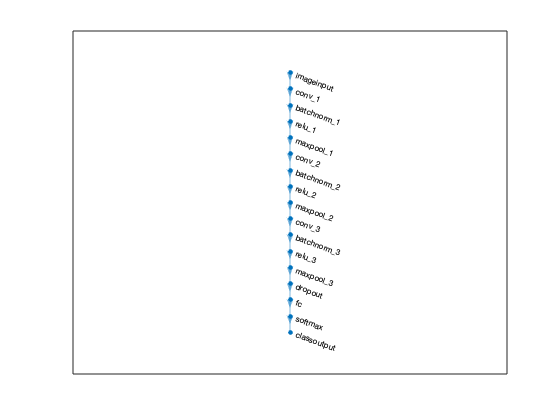

plot(layerGraph(layers));